load face_detect.mat
% vectorize the test images 
vectorized_images_train = reshape(faces_train, [size(faces_train,1)*size(faces_train,2),size(faces_train,3)]);
vectorized_images_test = reshape(faces_test_easy, [size(faces_test_easy,1)*size(faces_test_easy,2),size(faces_test_easy,3)]);

approx_num = 10;

% create a covariance matrix
mean_centered_data_train = mean_centered(vectorized_images_train);
mean_centered_data_test = mean_centered(vectorized_images_test);

% SVD
[largest_eigenvalues_train, largest_eigenvectors_train] = single_value_decomp(mean_centered_data_train, approx_num);

eigenvalues =    1.0e+05 *

    1.0158
    0.7629
    0.5339
    0.4103
    0.3546
    0.2887
    0.2633
    0.2485
    0.2277
    0.2266


lambda =    1.0e+05 *

    1.0158
    0.7629
    0.5339
    0.4103
    0.3546
    0.2887
    0.2633
    0.2485
    0.2277
    0.2266


v =     0.0016    0.0009    0.0048    0.0009    0.0053   -0.0058    0.0020   -0.0043   -0.0013    0.0053
    0.0017    0.0009    0.0050    0.0010    0.0054   -0.0058    0.0024   -0.0044   -0.0013    0.0051
    0.0018    0.0008    0.0053    0.0010    0.0055   -0.0056    0.0031   -0.0044   -0.0013    0.0046
    0.0019    0.0008    0.0056    0.0012    0.0056   -0.0056    0.0036   -0.0045   -0.0014    0.0041
    0.0021    0.0007    0.0058    0.0013    0.0057   -0.0055    0.0040   -0.0045   -0.0014    0.0036
    0.0022    0.0007    0.0060    0.0014    0.0057   -0.0056    0.0042   -0.0044   -0.0015    0.0035
    0.0022    0.0007    0.0061    0.0014    0.0058   -0.0057    0.0042   -0.0044   -0.0015    0.0037
    0.0023    0.0007    0.0061    0.0014    0.0058   -0.0058    0.0043   -0.0045   -0.0014    0.0038
    0.0023    0.0006    0.0062    0.0014    0.0059   -0.0058    0.0044   -0.0046   -0.0015    0.0038
    0.0024    0.0006    0.0062    0.0015    0.0060   -0.0058    0.0045   -0.0046   -0.0

[largest_eigenvalues_test, largest_eigenvectors_test] = single_value_decomp(mean_centered_data_test, approx_num);

eigenvalues =    1.0e+04 *

    4.3208
    2.9917
    2.2492
    1.4637
    1.4365
    1.2202
    1.1068
    1.0375
    0.9994
    0.9194


lambda =    1.0e+04 *

    4.3208
    2.9917
    2.2492
    1.4637
    1.4365
    1.2202
    1.1068
    1.0375
    0.9994
    0.9194


v =     0.0015    0.0011   -0.0037   -0.0073    0.0021    0.0010    0.0094   -0.0009    0.0073    0.0003
    0.0015    0.0011   -0.0036   -0.0073    0.0018    0.0009    0.0091   -0.0010    0.0073    0.0001
    0.0015    0.0010   -0.0033   -0.0074    0.0015    0.0006    0.0085   -0.0013    0.0072   -0.0003
    0.0016    0.0010   -0.0033   -0.0075    0.0013    0.0003    0.0085   -0.0016    0.0071   -0.0005
    0.0016    0.0010   -0.0036   -0.0077    0.0014    0.0010    0.0087   -0.0015    0.0072   -0.0008
    0.0016    0.0010   -0.0038   -0.0079    0.0016    0.0018    0.0093   -0.0013    0.0077   -0.0010
    0.0017    0.0010   -0.0039   -0.0080    0.0016    0.0021    0.0094   -0.0013    0.0078   -0.0007
    0.0017    0.0010   -0.0038   -0.0080    0.0016    0.0024    0.0095   -0.0015    0.0078   -0.0007
    0.0017    0.0010   -0.0037   -0.0082    0.0013    0.0022    0.0094   -0.0015    0.0079   -0.0010
    0.0017    0.0010   -0.0036   -0.0084    0.0009    0.0016    0.0091   -0.0018    0.0

**Weights of Faces**

Reduced_Train = largest_eigenvectors_train'*vectorized_images_train;
Reduced_Test = largest_eigenvectors_test'*vectorized_images_test;

Calculate the difference between weights of training / test

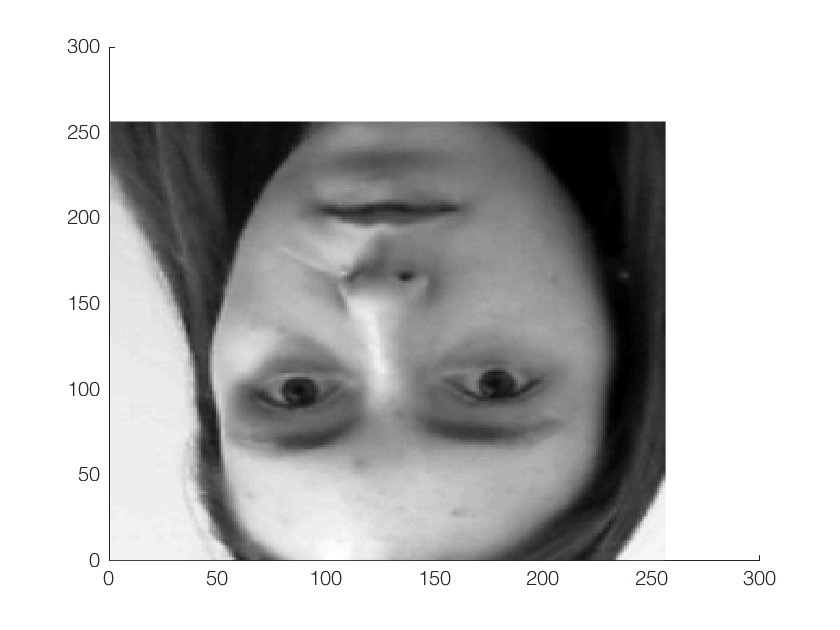

%distance = ones(length(Reduced_Test),length(Reduced_Train))

differences = repmat(Reduced_Test(:,21), size(Reduced_Test, 2));
distances = (sum(differences.^2)).^0.5;
minDist = min(distances);
index = find(minDist, 1);

%save for later - optimization
%face = faces_test_easy(:, :, 21);
%face_vector = reshape(face_vector, [size(face_vector, 1)*size(face_vector, 2)], size(face_vector, 3));

figure;
hold on;
image1 = imrotate(faces_test_easy(:,:,1), 180);
imagesc(faces_test_easy(:,:,21)); colormap('gray');
hold off;

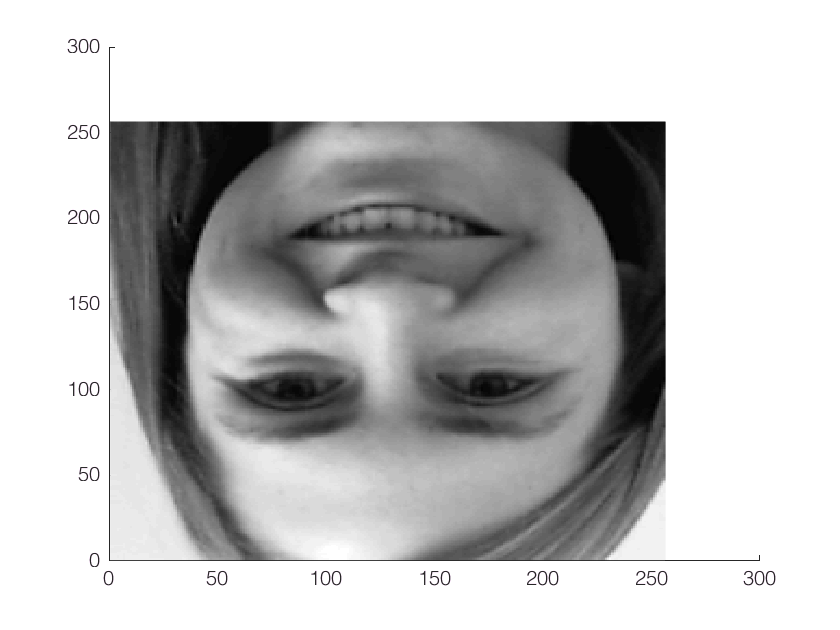


figure;
hold on;
image2 = imrotate(faces_train(:,:,21), 180);
imagesc(faces_train(:,:,21)); colormap('gray');
hold off;


% for j = 1:length(Reduced_Test)
%     for k = 1:length(Reduced_Train)
%         diff = Reduced_Train(:,k)-Reduced_Test(:,j)
%         distance(j,k) = sqrt(diff*diff')
%     end
% end
%  

    

Index the difference 

Creating mean centered data function 

function mean_centered_data = mean_centered(reshaped_image)
    o = ones(1,size(reshaped_image,2));
    m = mean(reshaped_image,2)*o;
    mean_centered_data = reshaped_image-m;
end

Single Value Decomposition's largest eigenvalues and eigenvectors

function [lambda, v] = single_value_decomp(faces,num)
    [U, S, V] = svd(faces, 'econ');
    eigenvalues = diag(S) 
    lambda = eigenvalues(1:num)
    v = U(:,1:num)
end